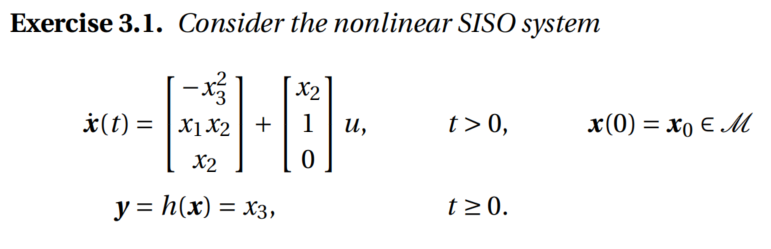

#### Answer

clear all
clc

syms x1 x2 x3 u

x = [x1; x2; x3; ];
f = [ (-x3^2 ) ;
        (x1*x2);
        (x2); ];
g = [x2;1;0];
h = x3;

*(a) **Determine the relative degree *`r`*.*

k = 0;
lglfh = LgLfh(f,g,h,x,0)

$$lglfh = 0$$

while lglfh == 0
    k = k+1;
    lglfh = LgLfh(f,g,h,x,k) % eq(3.9)
end

$$lglfh = 1$$


r = k+1 % k=r-1

r = 2

*(b) **Determine the Lie bracket of the vector fields *`f` *and *`g`* for *`k ``= 0,1,2`***.***

for j = 0:2
    adfg_k = adfg(f,g,x,j)
end

$$adfg\_k = \left(\begin{array}{c} x_{2}\\ 1\\ 0 \end{array}\right)$$

$$adfg\_k = \left(\begin{array}{c} x_{1}\,x_{2}\\ -{x_{2}}^{2}-x_{1}\\ -1 \end{array}\right)$$

$$adfg\_k = \left(\begin{array}{c} x_{2}\,{x_{1}}^{2}-x_{2}\,{x_{3}}^{2}-2\,x_{3}\\ x_{1}\,\left({x_{2}}^{2}+x_{1}\right)-3\,x_{1}\,{x_{2}}^{2}+{x_{3}}^{2}\\ {x_{2}}^{2}+x_{1} \end{array}\right)$$

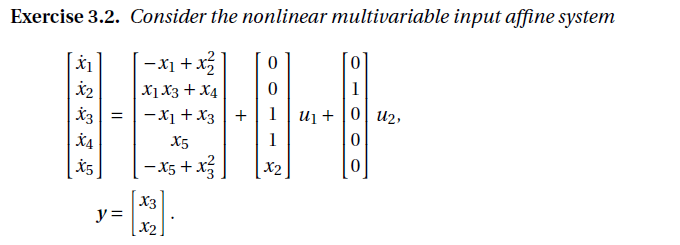

#### *(i) Determine the vectorial relative degree of the system.*

#### Answer

Build the system with symbolic math toolbox.

clear all
syms x1 x2 x3 x4 x5 u1 u2 v1 v2

f = [ -x1 + x2^2; x1*x3 + x4; -x1 + x3; x5; -x5+x3^2;]

$$f = \left(\begin{array}{c} {x_{2}}^{2}-x_{1}\\ x_{4}+x_{1}\,x_{3}\\ x_{3}-x_{1}\\ x_{5}\\ {x_{3}}^{2}-x_{5} \end{array}\right)$$

x = [x1; x2; x3; x4; x5; ]

$$x = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3}\\ x_{4}\\ x_{5} \end{array}\right)$$


g1 = [ 0; 0; 1; 1; x2;];
g2 = [ 0; 1; 0; 0; 0; ];
g = [g1, g2]

$$g = \left(\begin{array}{cc} 0 & 0\\ 0 & 1\\ 1 & 0\\ 1 & 0\\ x_{2} & 0 \end{array}\right)$$


h1 = x3;
h2 = x2;
h = [h1; h2;]

$$h = \left(\begin{array}{c} x_{3}\\ x_{2} \end{array}\right)$$


v = [v1; v2;];
u = [u1; u2;];

m = length(h);
n = length(x);

Since the input and output dimensions `m` are 2 rather than 1, the relative degree becomes a vector `(r1, r2)`.

r = zeros(1,m);
% Calculate relative degree
for i = 1:m
    k = 0;
    lglfh = LgLfh(f,g(:,i),h,x,0)
    while lglfh == zeros(m,1)
        k = k+1;
        lglfh = LgLfh(f,g(:,i),h,x,k) % eq(3.9)
    end
    r(:,i) = k+1;
end

$$lglfh = \left(\begin{array}{c} 1\\ 0 \end{array}\right)$$

$$lglfh = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

r

r =      1     1


#### *(ii) Examine the internal dynamics and make a statement about the stability of the zero dynamics.*

#### Answer

Calculate vector `a(x)`:

clear i
syms a [m 1]
for i = 1:m
    a(i) = Lfh(f,h(i),x,r(i)); % eq(3.12)   
end
a

$$a = \left(\begin{array}{c} x_{3}-x_{1}\\ x_{4}+x_{1}\,x_{3} \end{array}\right)$$

Calculate decoupling matrix `B(x)`:

clear i
syms B [m m]
for i = 1:m
    B(i,:) = LgLfh(f,g,h(i),x,r(i)-1); % eq(3.11)   
end
B

$$B = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

The determinant of matrix `B` is 1, therefore it is nonsigular. This guarantees that the relative degree is well defined. 

The diffeomosphism that shows the linear structrue of this feedback system is:

clear i k
syms z [n 1]
syms xi [sum(r) 1] % linearized states
k = 1;
for i = 1:m
    for j = 1:r(i)
        xi(k) = Lfh(f,h(i),x,j-1); % eq(3.14)
        k = k+1;
    end
end
xi

$$xi = \left(\begin{array}{c} x_{3}\\ x_{2} \end{array}\right)$$

z(1:sum(r)) = xi;

From the given vector `z`, it can be seen that there are 3 internal dynamics, for simplicity, we assign values as follows:

z(3) = x(1);
z(4) = x(4);
z(5) = x(5);
syms eta eta_dot [n-sum(r) 1] % internal dynamics
eta = z(3:5)

$$eta = \left(\begin{array}{c} x_{1}\\ x_{4}\\ x_{5} \end{array}\right)$$

z

$$z = \left(\begin{array}{c} x_{3}\\ x_{2}\\ x_{1}\\ x_{4}\\ x_{5} \end{array}\right)$$

eta_dot(1) = f(1) + g(1,:)*u;
eta_dot(2) = f(4) + g(4,:)*u;
eta_dot(3) = f(5) + g(5,:)*u;
eta_dot

$$eta\_dot = \left(\begin{array}{c} {x_{2}}^{2}-x_{1}\\ u_{1}+x_{5}\\ {x_{3}}^{2}-x_{5}+u_{1}\,x_{2} \end{array}\right)$$


eta_zero_dot = subs(eta_dot,xi,zeros(length(xi),1)) % zero dynamics

$$eta\_zero\_dot = \left(\begin{array}{c} -x_{1}\\ u_{1}+x_{5}\\ -x_{5} \end{array}\right)$$

In order to evaluate the stability of zero dynamics, the most intuitive way is to find its time domain solution.

syms x1(t) x5(t) z4(t) u1(t)
eq1 = diff(x1,t)== -x1

$$eq1(t) = \frac{\partial }{\partial t}x_{1}\left(t\right)=-x_{1}\left(t\right)$$

eq2 = diff(z4,t)== x5 + u1

$$eq2(t) = \frac{\partial }{\partial t}z_{4}\left(t\right)=u_{1}\left(t\right)+x_{5}\left(t\right)$$

eq3 = diff(x5,t)== -x5

$$eq3(t) = \frac{\partial }{\partial t}x_{5}\left(t\right)=-x_{5}\left(t\right)$$

eqs = [eq1 eq2 eq3];
dsolve(eqs)

ans = struct with fields:
    z4: C1 - C3*exp(-t) + int(u1(t), t, 'IgnoreSpecialCases', true, 'IgnoreAnalyticConstraints', true)
    x1: C2*exp(-t)
    x5: C3*exp(-t)


State `η1` and `η3` are asymptotically stable since they converge to zero as time increases; while `η2 `(or `z4` in the codes) is unstable because it depends on the integral of `u1`.

In this case, one has to introduce a new internal state to cancel out the influence by `u1`. Here we choose:

z(4) = x(4)-x(3); % design the z4 again
eta(2) = z(4); 
eta_dot(2) = f(4) + g(4,:)*u - f(3) - g(3,:)*u;
eta

$$eta = \left(\begin{array}{c} x_{1}\\ x_{4}-x_{3}\\ x_{5} \end{array}\right)$$

eta_dot % new internal dynamics

$$eta\_dot = \left(\begin{array}{c} {x_{2}}^{2}-x_{1}\\ x_{1}-x_{3}+x_{5}\\ {x_{3}}^{2}-x_{5}+u_{1}\,x_{2} \end{array}\right)$$

eta_zero_dot = subs(eta_dot,xi,zeros(length(xi),1)) % new zero dynamics

$$eta\_zero\_dot = \left(\begin{array}{c} -x_{1}\\ x_{1}+x_{5}\\ -x_{5} \end{array}\right)$$

Then one can calculate the time domain solution again to check the stability.

eq2 = diff(z4,t)== x1 + x5

$$eq2(t) = \frac{\partial }{\partial t}z_{4}\left(t\right)=x_{1}\left(t\right)+x_{5}\left(t\right)$$

eqs = [eq1 eq2 eq3]; % update the eq2
dsolve(eqs)

ans = struct with fields:
    z4: C1 + C2*exp(-t)
    x1: - C2*exp(-t) - C3*exp(-t)
    x5: C3*exp(-t)


Now all the zero dynamics are asymptotically stable.

#### *(iii) Design an output control with the method of exact input-output linearization. Use the reference trajectory *

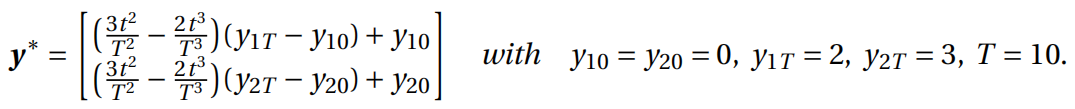

#### Answer

syms y1_ref(t) y2_ref(t)
y10 = 0;
y20 = 0;
y1T = 2;
y2T = 3;
T = 10;
y1_ref = (3*t^2/T^2 - 2*t^3/T^3)*(y1T - y10)+ y10;
y2_ref = (3*t^2/T^2 - 2*t^3/T^3)*(y2T - y20)+ y20;
y_ref = [y1_ref; y2_ref;]

$$y\_ref = \left(\begin{array}{c} \frac{3\,t^{2}}{50}-\frac{t^{3}}{250}\\ \frac{9\,t^{2}}{100}-\frac{3\,t^{3}}{500} \end{array}\right)$$

y_ref_dot = diff(y_ref,t)

$$y\_ref\_dot = \left(\begin{array}{c} \frac{3\,t}{25}-\frac{3\,t^{2}}{250}\\ \frac{9\,t}{50}-\frac{9\,t^{2}}{500} \end{array}\right)$$

The state feedback control which decouples and linearizes the I-O dynamics is:

clear i k
syms p [sum(r) 1]
k = 1;
for i = 1:m
    v(i) = 0;
    for l = 0:r(i)-1
        v(i) = v(i) - p(k)*(Lfh(f,h(i),x,l)-diff(y_ref(i),l)); % eq(3.26)
        k = k+1;
    end
end

v % introduced new input of the linearized system 

$$v = \left(\begin{array}{c} -p_{1}\,\left(\frac{t^{3}}{250}-\frac{3\,t^{2}}{50}+x_{3}\right)\\ -p_{2}\,\left(\frac{3\,t^{3}}{500}-\frac{9\,t^{2}}{100}+x_{2}\right) \end{array}\right)$$

u = B\(-a + y_ref_dot + v) % control law; eq(3.20)

$$u = \left(\begin{array}{c} \frac{3\,t}{25}+x_{1}-x_{3}-p_{1}\,x_{3}+\frac{3\,p_{1}\,t^{2}}{50}-\frac{p_{1}\,t^{3}}{250}-\frac{3\,t^{2}}{250}\\ \frac{9\,t}{50}-x_{4}-p_{2}\,x_{2}-x_{1}\,x_{3}+\frac{9\,p_{2}\,t^{2}}{100}-\frac{3\,p_{2}\,t^{3}}{500}-\frac{9\,t^{2}}{500} \end{array}\right)$$

The coefficients `p1` and `p2` are are coefficients of a Hurwitz polynomial. With this control law the system output will asymptotically converge towards `y∗` .

#### *(iv) Test your results using a *MATLAB / SIMULINK *simulation.*

#### Answer

One can use `matlabFunctionBlock(’blockname’, symexpr)` to convert the symbolic expression to `MATLAB-FUNCTION `block. 

% new_system('Ex3_2_4')
% open_system('Ex3_2_4')
% 
% u = subs(u,[p1, p2],[1 1])

$$u = \left(\begin{array}{c} -\frac{t^{3}}{250}+\frac{6\,t^{2}}{125}+\frac{3\,t}{25}+x_{1}-2\,x_{3}\\ -\frac{3\,t^{3}}{500}+\frac{9\,t^{2}}{125}+\frac{9\,t}{50}-x_{2}-x_{4}-x_{1}\,x_{3} \end{array}\right)$$

% matlabFunctionBlock('Ex3_2_4/controller', u, y_ref,'Vars',{x, t},'Optimize',false)
% 
% clear u
% syms u1 u2
% u = [u1; u2];
% dx = f + g*u

$$dx = \left(\begin{array}{c} {x_{2}}^{2}-x_{1}\\ u_{2}+x_{4}+x_{1}\,x_{3}\\ u_{1}-x_{1}+x_{3}\\ u_{1}+x_{5}\\ {x_{3}}^{2}-x_{5}+u_{1}\,x_{2} \end{array}\right)$$

% y = h

$$y = \left(\begin{array}{c} x_{3}\\ x_{2} \end{array}\right)$$

% matlabFunctionBlock('Ex3_2_4/model', y, dx,'Vars',{u, x},'Optimize',false)
% 
% save_system('Ex3_2_4')

Since the section above can be only used once, we commented it for convenience.

From the simulation results in Simulink it can be concluded that the outputs can track the references with a high accuracy, even though the tracking errors increase over time. Therefore, the system is stablized by the feedback control law.